clear
clc
digits(4)

Definizione masse e gravità

% Massa singola ruota
m_r = sym('3');

% Massa asta
m_a = sym('3.5');

% Massa uomo (da far variare poi)
m_c = sym('70');

% Massa carello(base) + batterie
m_b = sym('34.4');

% Massa totale del sistema
M = m_a+m_b+m_c+2*m_r;

% Costante gravitazionale
g = sym('9.81');

Definizione inerzie

% Inerzia asta
J_a = sym('0.1669');

% Inerzia della base
J_b = sym('0.6667');

% Inerzia del corpo (TODO: lungo asse z????)
J_c = 0.5 * m_c * (0.25 ^ 2 + 0.35 ^ 2);

% Inerzia della singola ruota
J_r = sym('0.1452');

Definizione delle altezze [m]

% Altezza asta
h_a = sym('1.4');

% Altezza base
h_b = sym('0.2');

% Profondità base
w_b = sym('0.5');

% Posizione baricentro base (valore assoluto)
z_b = sym('0.1');

% Posizione baricentro corpo umano
h_c = sym('1.70'); % Altezza uomo

% Raggio ruota
r = sym('0.22')

$$r = 0.22$$

Definizione delle costanti geometriche a e beta (come in immagine)

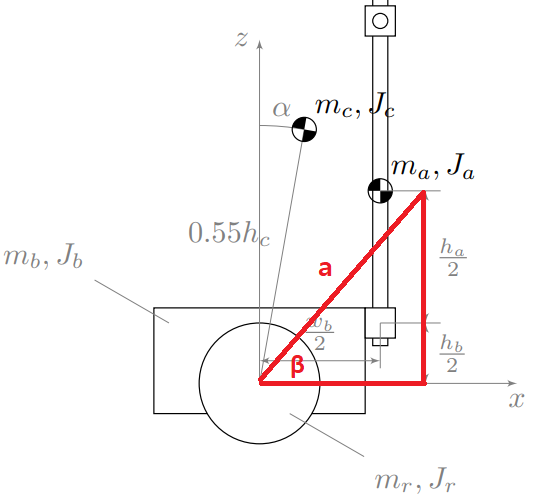

temp_1 = (h_a / 2) + (h_b / 2);
temp_2 = w_b / 2;
l_c = 0.55 * h_c;
l_b = - 0.1;
l_a = vpa(sqrt((temp_1)^2 + (temp_2)^2));

Definizione delle variabili

syms t; % tempo
syms T; % energia cinetica del sistema
syms U; % energia potenziale del sistema
syms alpha; % Angolo di offset statico che sposta in avanti il baricentro
syms beta;%altro angolo statico, vedi disegno
% syms l_c l_a l_b m_a m_c m_r m_b J_r J_b J_a J_c g;
% Coordinate libere
syms phi(t); % posizione carrello
vel = diff(phi, t); %velocità carello
syms theta(t); % angolo inclinazione
vel_ang = diff(theta, t);%vel angolare
syms b; % Attrito viscoso
syms q_1 q_1_p q_2 q_2_p;
alpha = 0;
beta = vpa(atan(temp_1 / temp_2));


Definisco il problema per il punto Pa

P_a = [phi/r+l_a*sin(theta+beta);l_a*cos(theta+beta);theta]

$$P\_a(t) = \left(\begin{array}{c} 0.8382\,\sin\left(\theta \left(t\right)+1.268\right)+4.545\,\varphi \left(t\right)\\ 0.8382\,\cos\left(\theta \left(t\right)+1.268\right)\\ \theta \left(t\right) \end{array}\right)$$

V_a = diff(P_a,t);
M_a = [m_a,0,0;0,m_a,0;0,0,J_a];
T_a = 1/2 * transpose(V_a) * M_a * V_a;
U_a = m_a * g * l_a*cos(theta+beta);
L_a = T_a - U_a;


Definisco il problema per il punto Pc

P_c = [phi/r+l_c*sin(theta+alpha);l_c*cos(theta+alpha);alpha+theta]

$$P\_c(t) = \left(\begin{array}{c} 0.935\,\sin\left(\theta \left(t\right)\right)+4.545\,\varphi \left(t\right)\\ 0.935\,\cos\left(\theta \left(t\right)\right)\\ \theta \left(t\right) \end{array}\right)$$

V_c = diff(P_c,t);
M_c = [m_c,0,0;0,m_c,0;0,0,J_c];
T_c = 1/2 * transpose(V_c) * M_c * V_c;
U_c = m_c * g * l_c*cos(alpha+theta);
L_c = T_c - U_c;

Definisco il problema per il punto Pb

P_b = [phi/r+l_b*sin(theta);l_b*cos(theta);theta]

$$P\_b(t) = \left(\begin{array}{c} 4.545\,\varphi \left(t\right)-\frac{\sin\left(\theta \left(t\right)\right)}{10}\\ -\frac{\cos\left(\theta \left(t\right)\right)}{10}\\ \theta \left(t\right) \end{array}\right)$$

V_b = diff(P_b,t);
M_b = [m_b,0,0;0,m_b,0;0,0,J_b];
T_b = 1/2 * transpose(V_b) * M_b * V_b;
U_b = m_b * g * l_b*cos(theta);
L_b = T_b - U_b;

Definisco il problema per il punto Pr

P_r = [phi/r;0;theta]

$$P\_r(t) = \left(\begin{array}{c} 4.545\,\varphi \left(t\right)\\ 0\\ \theta \left(t\right) \end{array}\right)$$

V_r = diff(P_r,t);
M_r = [m_r,0,0;0,m_r,0;0,0,J_r];
T_r = 1/2 * transpose(V_r) * M_r * V_r;
U_r = 0;
L_r = T_r - U_r;

Eulero Lagrange

syms q_1 q_1_p q_2 q_2_p;
L = collect(simplify(2*L_r + L_a + L_b +L_c))

$$L(t) = \begin{array}{l} 27.47\,\sin\left(\theta \left(t\right)\right)-616.9\,\cos\left(\theta \left(t\right)\right)+1177.0\,{\left(\frac{\partial }{\partial t}\varphi \left(t\right)\right)}^{2}+35.8\,\sigma_{1}+8.997e-7\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\sigma_{1}+285.8\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)-12.73\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2} \end{array}$$

L_q = subs(L,{phi,vel,theta,vel_ang},{q_1 q_1_p q_2 q_2_p});
dL_dq2p = diff(L_q,q_2_p);
dL_dq2 = diff(L_q,q_2);
dL_dvel_ang = subs(dL_dq2p,{q_1 q_1_p q_2 q_2_p},{phi,vel,theta,vel_ang});
dL_dtheta = subs(dL_dq2,{q_1 q_1_p q_2 q_2_p},{phi,vel,theta,vel_ang});
dL_dvel_ang_dt = diff(dL_dvel_ang,t);
% risultato = collect(dL_dvel_ang_dt - dL_dtheta + (b * vel_ang)) attrito
E_L_theta = collect(dL_dvel_ang_dt - dL_dtheta == 0)

$$E\_L\_theta(t) = \begin{array}{l} 1.799e-6\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\sigma_{2}+285.8\,\cos\left(\theta \left(t\right)\right)\,\sigma_{3}-12.73\,\sin\left(\theta \left(t\right)\right)\,\sigma_{3}+71.6\,\sigma_{2}+8.997e-7\,{\cos\left(\theta \left(t\right)\right)}^{2}\,\sigma_{1}-8.997e-7\,{\sin\left(\theta \left(t\right)\right)}^{2}\,\sigma_{1}-27.47\,\cos\left(\theta \left(t\right)\right)-616.9\,\sin\left(\theta \left(t\right)\right)=0\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}\\ \sigma_{2}=\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)\\ \sigma_{3}=\frac{\partial^{2}}{\partial t^{2}}\varphi \left(t\right) \end{array}$$

eulero lagrange wrt phi

dL_dq1p = diff(L_q,q_1_p);
dL_dq1 = diff(L_q,q_1);
dL_dvel = subs(dL_dq1p,{q_1 q_1_p q_2 q_2_p},{phi,vel,theta,vel_ang});
dL_dphi = subs(dL_dq1,{q_1 q_1_p q_2 q_2_p},{phi,vel,theta,vel_ang});
dL_dvel_dt = diff(dL_dvel,t);
%%attenzione, ci andrebbe una forza f dall'altro lato!
syms F;
E_L_phi = collect(simplify(dL_dvel_dt - dL_dphi == F))

$$E\_L\_phi(t) = F+12.73\,\cos\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}+285.8\,\sin\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}+12.73\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)=285.8\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)+2353.0\,\frac{\partial^{2}}{\partial t^{2}}\varphi \left(t\right)$$

Risolviamo le equazioni

acc_ang = diff(theta,t,2);
acc = diff(phi,t,2);
syms q1_s q2_s;
eqns = [subs(E_L_theta, {acc,acc_ang},{q1_s,q2_s}),subs(E_L_phi, {acc,acc_ang},{q1_s,q2_s})];
[teta2,phi2] = solve(eqns, [q1_s q2_s])

$$teta2 = \begin{array}{l} \frac{0.00025\,\left(7.16e+15\,F-1.76e+19\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)+2.572e+10\,{\cos\left(\theta \left(t\right)\right)}^{3}\,\sigma_{1}+1.145e+9\,{\sin\left(\theta \left(t\right)\right)}^{3}\,\sigma_{1}-7.851e+17\,\sigma_{2}+7.851e+17\,\sigma_{3}+9.112e+16\,\cos\left(\theta \left(t\right)\right)\,\sigma_{1}+2.047e+18\,\sin\left(\theta \left(t\right)\right)\,\sigma_{1}+1.799e+8\,F\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)+2.572e+10\,\cos\left(\theta \left(t\right)\right)\,\sigma_{3}\,\sigma_{1}+1.145e+9\,\sigma_{2}\,\sin\left(\theta \left(t\right)\right)\,\sigma_{1}\right)}{-2.043e+15\,\sigma_{2}+1.819e+14\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)-4.049e+12\,\sigma_{3}+4.212e+15}\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}\\ \sigma_{2}={\cos\left(\theta \left(t\right)\right)}^{2}\\ \sigma_{3}={\sin\left(\theta \left(t\right)\right)}^{2} \end{array}$$

$$phi2 = \begin{array}{l} \frac{0.05\,\left(3.232e+16\,\cos\left(\theta \left(t\right)\right)+7.259e+17\,\sin\left(\theta \left(t\right)\right)+6.364e+12\,F\,\sin\left(\theta \left(t\right)\right)-1.819e+15\,\sigma_{2}\,\sigma_{1}+1.819e+15\,\sigma_{3}\,\sigma_{1}-1.429e+14\,F\,\cos\left(\theta \left(t\right)\right)-4.077e+16\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\sigma_{1}\right)}{-2.043e+15\,\sigma_{2}+1.819e+14\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)-4.049e+12\,\sigma_{3}+4.212e+15}\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}\\ \sigma_{2}={\cos\left(\theta \left(t\right)\right)}^{2}\\ \sigma_{3}={\sin\left(\theta \left(t\right)\right)}^{2} \end{array}$$

linearizzazione intorno all'equilibrio [0,0,0,0], uso la matrice A come in e-05 dynamics

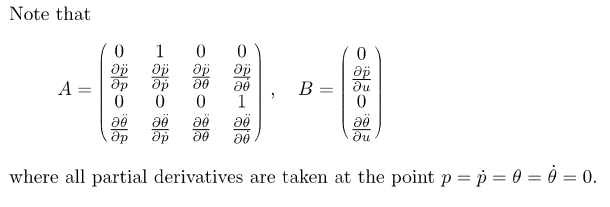

syms u;
teta2_differenziabile = subs(teta2,{phi,vel,theta,vel_ang,F},{q_1 q_1_p q_2 q_2_p u});
phi2_differenziabile = subs(phi2,{phi,vel,theta,vel_ang,F},{q_1 q_1_p q_2 q_2_p u});
%phi,phi_primo,theta,theta_primo,F
equilibrio = {0,0,0,0,0}

equilibrio = 1×5 cell array
    {[0]}    {[0]}    {[0]}    {[0]}    {[0]}


A11 = 0;
A12 = 1;
A13 = 0;
A14 = 0;
A21 = subs(diff(phi2_differenziabile,q_1),{q_1 q_1_p q_2 q_2_p u},equilibrio);
A22 = subs(diff(phi2_differenziabile,q_1_p),{q_1 q_1_p q_2 q_2_p u},equilibrio);
A23 = subs(diff(phi2_differenziabile,q_2),{q_1 q_1_p q_2 q_2_p u},equilibrio);
A24 = subs(diff(phi2_differenziabile,q_2_p),{q_1 q_1_p q_2 q_2_p u},equilibrio);
A31 = 0;
A32 = 0;
A33 = 0;
A34 = 1;
A41 = subs(diff(teta2_differenziabile,q_1),{q_1 q_1_p q_2 q_2_p u},equilibrio);
A42 = subs(diff(teta2_differenziabile,q_1_p),{q_1 q_1_p q_2 q_2_p u},equilibrio);
A43 = subs(diff(teta2_differenziabile,q_2),{q_1 q_1_p q_2 q_2_p u},equilibrio);
A44 = subs(diff(teta2_differenziabile,q_2_p),{q_1 q_1_p q_2 q_2_p u},equilibrio);
A = [A11 A12 A13 A14;A21 A22 A23 A24;A31 A32 A33 A34; A41 A42 A43 A44]

$$A = \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ 0 & 0 & 16.67 & 0\\ 0 & 0 & 0 & 1\\ 0 & 0 & -2.02 & 0 \end{array}\right)$$

B11 = 0;
B21 = subs(diff(phi2_differenziabile,u),{q_1 q_1_p q_2 q_2_p u},equilibrio);
B31 = 0;
B41 = subs(diff(teta2_differenziabile,u),{q_1 q_1_p q_2 q_2_p u},equilibrio);
B = [B11;B21;B31;B41];
%volgio come uscita l'angolo
C = [0,0,1,0]

C =      0     0     1     0


D = 0;
syms s G(s);
G = collect(simplify(C*(s*eye(4)-A)^-1*B+D))

$$G = \frac{82490.0}{1.0e+8\,s^{2}+2.02e+8}$$

## SIMULAZIONE

[num, den] = numden(G);

$$num = 8.249$$

$$den = 10000.0\,s^{2}+20200.0$$

NUM = [82490, 0] % Adding pole

NUM =        82490           0


den_coeff = coeffs(den)

$$den\_coeff = \left(\begin{array}{cc} 20200.0 & 10000.0 \end{array}\right)$$

% I guess no coefficient for s term
DEN = [1.0e+8, 0, 2.02e+8]

DEN =    100000000           0   202000000



t_end = 100;
Ts = 1/100;
control_on = 0;
k_p = -1;

sim  VABSim 

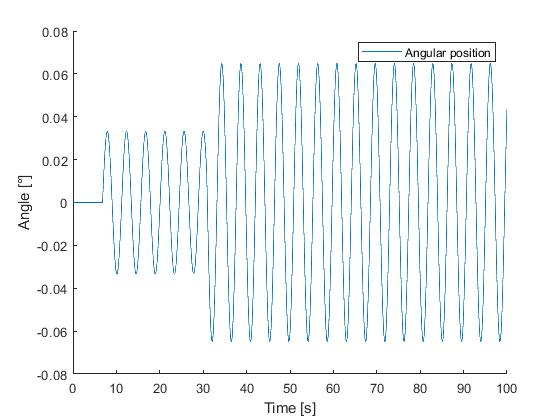

no_control_sim(1,:) = sim_out;

figure
hold on
plot(tout, no_control_sim)
xlabel('Time [s]')
ylabel('Angle [°]')

legend('Angular position')

control_on = 1;
k_p = -1;

sim  VABSim 

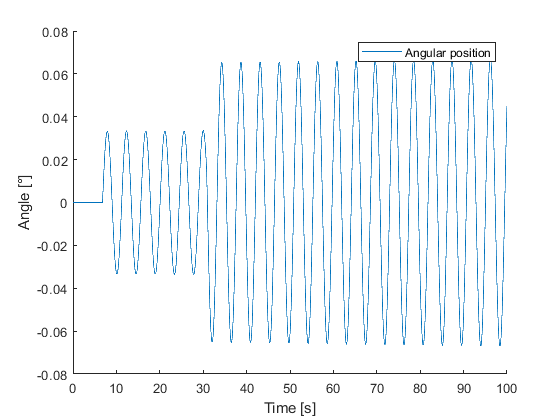

control_sim(1,:) = sim_out;

figure
hold on
plot(tout, control_sim)
xlabel('Time [s]')
ylabel('Angle [°]')

legend('Angular position')